# Portfolio Performance Attribution Analysis

In this example, we show how simple and powerful it is to use Matlab (especailly table operation) to perform Performance Attribution analysis.

### Single Period Brinson Model

*Brinson model:* *value added return* can be segmented into the impact of assigning the asset weight of the portfolio to various economic sectors and the impact of selecting securities within those sectors.


$$R_{\textrm{ValueAdded}} =\sum_{i=1}^{N_s } R_{\textrm{Pi}} W_{\textrm{Pi}} -\sum_{i=1}^{N_s } R_{\textrm{Bi}} W_{\textrm{Bi}}$$


                 $=\sum_{i=1}^{N_s } R_{\textrm{Bi}} \left(W_{\textrm{Pi}} -W_{\textrm{Bi}} \right)$          Pure sector allocation, portfolio managers' responsibility

                $+\;\;\sum_{i=1}^{N_s } \left(R_{\textrm{Pi}} -R_{\textrm{Bi}} \right)$$W_{\textrm{Bi}}$                 Within-sector selection, security analysts' responsibility

                $+\;\;\sum_{i=1}^{N_s } \left(R_{\textrm{Pi}} -R_{\textrm{Bi}} \right)\left(W_{\textrm{Pi}} -W_{\textrm{Bi}} \right)$          Allocation/selection interaction, joint effect

where 

$N_s$ is the total number of sectors

$R_{\textrm{Pi}}$ is the return of sector i in the portfolio

$W_{\textrm{Pi}}$ is the allocated weight for sector i in the portfolio

$R_{\textrm{Bi}}$ is the return of sector i in the benchmark 

$W_{\textrm{Bi}}$ is the allocated weight for sector i in the benchmark

 $R_B$ is the overall benchmark return.  

$R_{\textrm{Pi}}$ ,$W_{\textrm{Pi}}$, $R_{\textrm{Bi}}$, $W_{\textrm{Bi}}$  are computed by aggregating all asset weights and returns in the given portfolio and benchmark as follows:

$W_{\textrm{Pi}} =\sum_j w_{\textrm{pj}}$,$\;\;R_{\textrm{Pi}} =\frac{\sum_j r_{\textrm{Pj}} w_{\textrm{Pj}} }{\sum_j w_{\textrm{pj}} }$,  $W_{\textrm{Bi}} =\sum_j w_{\textrm{Bj}}$,$\;\;R_{\textrm{Bi}} =\frac{\sum_j r_{\textrm{Bj}} w_{\textrm{Bj}} }{\sum_j w_{\textrm{Bj}} }$

where 

$r_{\textrm{Pj}}$, $w_{\textrm{Pj}}$  are the return and weight of asset j that belongs to sector i in the portfolio 

$r_{\textrm{Bj}}$, $w_{\textrm{Bj}}$  are the return and weight of asset j that belongs to sector i in the benchmark.

### Factor-based Performance Attribution

Factor models decompose *asset returns* into a systematic component that is explained by factors and a residual component that is not. One big advantage of this approach is that it allows one to define their own attribution model by easily incorporating multiple variables (factors). 

$r_i =\sum_k X_{\textrm{ik}} f_k +u_i$, 

where $X_{\textrm{ik}}$ is the exposure of stock i to factor k (or factor loadings), $f_k$ is the return for factor k, $u_i$ is the residual return of the stock. *It is assumed that the stock exposures are known at the start of the evaluation period, and the factor returns are estimated by cross-sectional regression at the end of the evaluation period. *Active return can be attributed by aggregating asset returns to the factor level.


$$R_{\textrm{ValueAdded}} =\sum_k X_k^A f_k +\sum_i w_i^A u_i \;\;\;,$$



$$X_k^A =\sum_i w_i^A X_{\textrm{ik}} =\sum_i \left(w_{\textrm{Pi}} {-w}_{\textrm{Bi}} \right)X_{\textrm{ik}}$$


Where $w_i^A$ is the active weight of asset i, $X_k^A$ is the active exposure to factor k for all assets in the portfolio.

#### Load data

The dataset is simulated and used for demonstration purposes in this example.

load('demo_data.mat');
portData(1:7, :)

ans = 7×5 table
    AssetTicker    AssetWgt    AssetRetn       Sector                     Security               
    ___________    ________    __________    ___________    _____________________________________

       A             0.01      -0.0030997    Health Care    {'Agilent Technologies Inc'         }
       ALGN          0.01        0.091135    Health Care    {'Align Technology'                 }
       AON           0.01         -0.0667    Financials     {'Aon plc'                          }
       APC           0.01         -0.4817    Energy         {'Anadarko Petroleum Corp'          }
       AXP           0.01        -0.11152    Financials     {'American Express Co'              }
       BK            0.01       -0.047597    Financials     {'The Bank of New York Mellon Corp.'}
       BSX           0.01    

benchmarkData(1:7, :)

ans = 7×5 table
    AssetTicker    AssetWgt     AssetRetn             Sector                      Security          
    ___________    _________    __________    ______________________    ____________________________

       A           0.0021739    -0.0030997    Health Care               {'Agilent Technologies Inc'}
       AAP         0.0021739      0.034789    Consumer Discretionary    {'Advance Auto Parts'      }
       AAPL        0.0021739      -0.18213    Information Technology    {'Apple Inc.'              }
       ABBV        0.0021739     -0.084106    Health Care               {'AbbVie Inc.'             }
       ABC         0.0021739      -0.10013    Health Care               {'AmerisourceBergen Corp'  }
       ABT         0.0021739     -0.044468    Health Care               {'Abbott Laboratories'     }
     

#### Some analysis and visualization

 Use the above data which is on the asset level, and group them to the sector level, and conduct the performance analysis.

unique(portData.Sector)

ans = 11×1 categorical array
     Communication Services 
     Consumer Discretionary 
     Consumer Staples 
     Energy 
     Financials 
     Health Care 
     Industrials 
     Information Technology 
     Materials 
     Real Estate 
     Utilities 


format compact
summary(portData)

Variables:
    AssetTicker: 70×1 categorical
        Properties:
            Description:  Original column heading: 'Ticker symbol'
        Values:
            A          1    
            ALGN       1    
            AON        1    
            APC        1    
            AXP        1    
            BK         1    
            BSX        1    
            CA         1    
            CBOE       1    
            CI         1    
            CLX        1    
            CMA        1    
            COF        1    
            COST       1    
            CVS        1    
            DIS        1    
            EMR        1    
            EQT        1    
            FL         1    
            FOXA       1    
            GD         1    
            GM         1    
            HAS        1    
            HCP        1    
            IDXX       1    
            IPG        1    
            IR         1    
            JCI        1    
            K          

summary(benchmarkData)

Variables:
    AssetTicker: 460×1 categorical
        Properties:
            Description:  Original column heading: 'Ticker symbol'
        Values:
            A           1    
            AAP         1    
            AAPL        1    
            ABBV        1    
            ABC         1    
            ABT         1    
            ACN         1    
            ADBE        1    
            ADI         1    
            ADM         1    
            ADP         1    
            ADS         1    
            ADSK        1    
            AEE         1    
            AEP         1    
            AES         1    
            AET         1    
            AFL         1    
            AGN         1    
            AIG         1    
            AIV         1    
            AIZ         1    
            AJG         1    
            AKAM        1    
            ALB         1    
            ALGN        1    
            ALK         1    
            ALL         

Very easy to query from the table, e.g. find me the assets with Sector in 'Engery', or sort by 'AssetRetn':

rows = portData.Sector=='Energy';
portData(rows, :)

ans = 3×5 table
    AssetTicker    AssetWgt    AssetRetn    Sector               Security            
    ___________    ________    _________    ______    _______________________________
        APC          0.01       -0.4817     Energy    {'Anadarko Petroleum Corp'    }
        EQT          0.01      -0.41878     Energy    {'EQT Corporation'            }
        NOV          0.01       -0.3882     Energy    {'National Oilwell Varco Inc.'}

sortrows(portData, 'Sector')

ans = 70×5 table
    AssetTicker    AssetWgt    AssetRetn             Sector                          Security              
    ___________    ________    __________    ______________________    ____________________________________
       DIS             0.01     -0.053589    Communication Services    {'The Walt Disney Company'         }
       FOXA            0.01      -0.21207    Communication Services    {'Twenty-First Century Fox Class A'}
       IPG             0.01       0.10489    Communication Services    {'Interpublic Group'               }
       NFLX            0.01        0.4429    Communication Services    {'Netflix Inc.'                    }
       NWS             0.01       -0.1313    Communication Services    {'News Corp. Class B'              }
       T           0.044938    -0.0034752    Communicatio

#### Brinson attribution analysis

Let's analyze the performance by sector: need to group assets by sector for both the given portfolio and benchmark, and compute the sector weghts and returns. This can be easily done using *findgroups* for table operations. 'pa_brinson' function implements the single period brinson model.

 results = pa_brinson(portData, benchmarkData)

results = 12×9 table
            Sector            PortRetn    BenchRetn    PortWgt    BenchWgt    PureSectorAllocation    WithinSectorSelection    AllocSelecInteraction    TotalValueAdded
    ______________________    ________    _________    _______    ________    ____________________    _____________________    _____________________    _______________
    Communication Services     1.9253      -1.1249     10.494           5            0.15032                 0.15251                   0.16757              0.47039    
    Consumer Discretionary    -4.2695      -2.2786          8      13.478          -0.086688                -0.26834                   0.10907             -0.24596    
 

The last row shows the total portfolio return and benchmark return, also the total effects of sector allocation and stock selection.

results(end, :)

ans = 1×9 table
    Sector     PortRetn    BenchRetn    PortWgt    BenchWgt    PureSectorAllocation    WithinSectorSelection    AllocSelecInteraction    TotalValueAdded
    _______    ________    _________    _______    ________    ____________________    _____________________    _____________________    _______________
    Summary     2.3524      -3.861        100        100              4.1366                  0.31905                  1.7578                6.2134     

We can also plot the active returns resulting from allocation/selection/interaction effects for each sector.

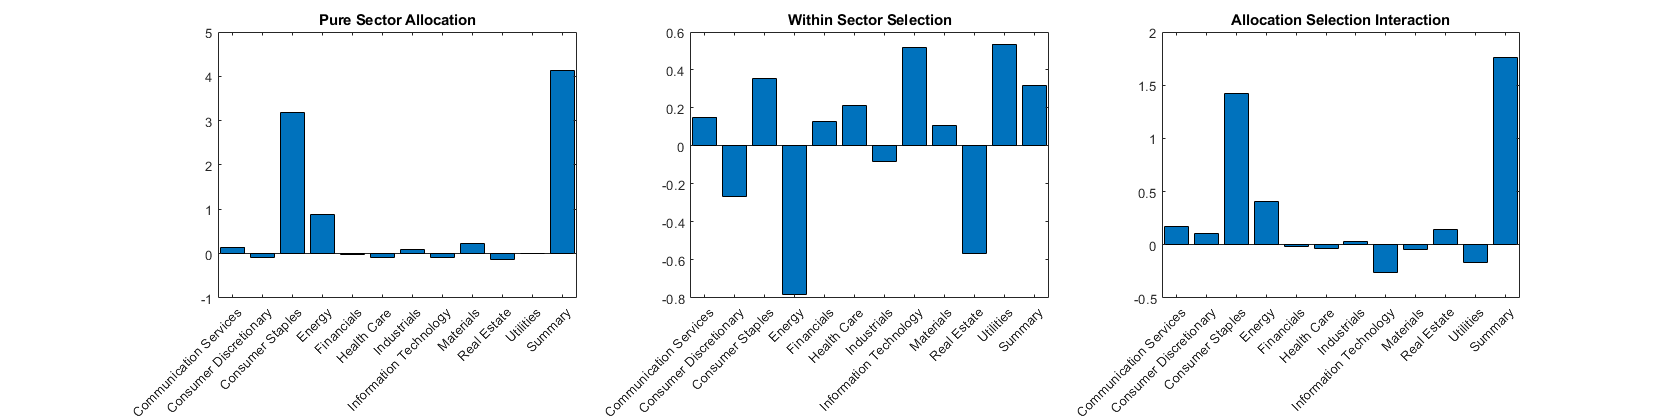

f=figure;
f.Position(3)= 3*f.Position(3);
subplot(1,3,1);
bar(results.Sector, results.PureSectorAllocation); 
title('Pure Sector Allocation');
subplot(1,3,2);
bar(results.Sector, results.WithinSectorSelection);
title('Within Sector Selection');
subplot(1,3,3);
bar(results.Sector, results.AllocSelecInteraction); 
title('Allocation Selection Interaction');

#### Factor-based Analysis

We can acutally think of the Brinson sector-based attribution analysis as a special case of factor-based analysis. This is done by considering the different sectors as different factors driving the active portfolio returns. Our assumption is that the factor loadings $X_{\textrm{ik}}$ are known at the beginning; here in our case $X_{\textrm{ik}}$ is 1, if stock i belongs to sector k. So, we need to run regression to get the factor returns.

To replicate the results from the Brinson model, we note that the factor returns are different between the portfolio and benchmark, due to the difference in the underlying strategies.

% formulate active weight for each asset from the given dataset.
assetTable = outerjoin(portData, benchmarkData, 'MergeKeys',true,'type', 'right', ...
    'LeftKey', 'AssetTicker', 'RightKey', 'AssetTicker', ...
    'LeftVariables', {'AssetTicker', 'AssetWgt'}, 'RightVariables', {'AssetWgt', 'AssetRetn', 'Sector'});
assetTable = fillmissing(assetTable, 'constant', 0, 'DataVariables',{'AssetWgt_portData'});
assetTable.ActiveWgt = assetTable.AssetWgt_portData - assetTable.AssetWgt_benchmarkData;
sectors = unique(assetTable.Sector);
assetTable(1:7,:)

ans = 7×6 table
    AssetTicker    AssetWgt_portData    AssetWgt_benchmarkData    AssetRetn       Sector       ActiveWgt
    ___________    _________________    ______________________    __________    ___________    _________
       A                 0.01                 0.0021739           -0.0030997    Health Care    0.0078261
       ALGN              0.01                 0.0021739             0.091135    Health Care    0.0078261
       AON               0.01                 0.0021739              -0.0667    Financials     0.0078261
       APC               0.01                 0.0021739              -0.4817    Energy         0.0078261
       AXP               0.01                 0.0021739             -0.11152    Financials     0.0078261
       BK                0.01                

*Sector Allocation effect:* we can use factor-based analysis to compute the allocation effect in the Brinson model. In this case, we would like to use weighted regression to find benchmark factor return and active exposure for each factor.

1) Formulate asset exposure to factors, should usually be predefined. We see that the entry in Xik is 1 if asset i belongs to sector k.

Xik_B = (benchmarkData.Sector==sectors');
Xik_B(1:5,:);

2) Run weighted regression to get the benchmark factor return fk: r_i = Xik * f_k. 

warning('off');
mdl = fitlm(Xik_B, benchmarkData.AssetRetn, 'Intercept', false, 'Weights', benchmarkData.AssetWgt)

mdl = Linear regression model:
    y ~ x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11

Estimated Coefficients:
           Estimate        SE        tStat        pValue  
           _________    ________    ________    __________
    x1     -0.011249    0.034321    -0.32774       0.74326
    x2     -0.022786    0.020904       -1.09       0.27629
    x3      0.092173    0.031106      2.9632     0.0032068
    x4      -0.30578    0.030565     -10.004    2.0962e-21
    x5     -0.030001    0.021613     -1.3881       0.16579
    x6     0.0021366     0.02125     0.10055       0.91995
    x7     -0.053316    0.020738      -2.571      0.010462
    x8     -0.023853    0.021996     -1.0844       0.27875
    x9 

The factor returns are the coefficents from the trained model. We can see that they exactly match the benchmark sector returns obtained from Brinson model.

fk_B = mdl.Coefficients.Estimate(1:end); 
[fk_B*100, results.BenchRetn(1:end-1)]

ans =    -1.1249   -1.1249
   -2.2786   -2.2786
    9.2173    9.2173
  -30.5781  -30.5781
   -3.0001   -3.0001
    0.2137    0.2137
   -5.3316   -5.3316
   -2.3853   -2.3853
  -15.0496  -15.0496
    3.4787    3.4787


3) Compute the factor contribution for allocation effects: 


$$R_{\textrm{Allocation}} =\sum_k X_k^A f_k$$


X_act_exposure = assetTable.ActiveWgt'*(assetTable.Sector==sectors');
R_allc = X_act_exposure*fk_B;

We can see that R_allc matches the total 'pure sector allocation effect' from Brinson model, by comparing the values below:

R_allc*100

ans = 4.1366

results.PureSectorAllocation(end)

ans = 4.1366

*Within-Sector Selection effect*: We can use factor-based regression analysis to replicate the within-sector selection effects in Brinson model. In this case, both portfolio factor returns and benchmark factor returns are needed.

Xik_P = (portData.Sector==sectors');
mdl_P = fitlm(Xik_P, portData.AssetRetn, 'Intercept', false, 'Weights', portData.AssetWgt);
fk_P = mdl_P.Coefficients.Estimate;
[fk_P*100 results.PortRetn(1:end-1)]

ans =     1.9253    1.9253
   -4.2695   -4.2695
   15.0331   15.0331
  -42.9559  -42.9559
   -1.9611   -1.9611
    1.8558    1.8558
   -5.9437   -5.9437
    1.8943    1.8943
  -12.8452  -12.8452
   -4.9497   -4.9497


We have already found the benchmark factor returns fk_B. It is shown that R_wss matches the within-sector selection effect in the Brinsion model.


$$X_k^B =\sum_i w_{\textrm{Bi}} X_{\textrm{ik}}$$



$$R_{\textrm{Selection}} =\sum_k X_k^B \left(f_k^P -f_k^B \right)$$


R_wss = (benchmarkData.AssetWgt'*Xik_B)*(fk_P - fk_B);
R_wss*100

ans = 0.3191

results.WithinSectorSelection(end)

ans = 0.3191

In summary, We have shown how to conduct Brinson and factor-based analysis for performance attribution. We also showed that Brinson model is a special case of factor-based performance analysis, using sectors as the factors. To perform factor-based attribution analysis, we need to have predefined factor loading Xik and asset return ri, so that we can extract the factor return fk. Together with the portfolio and benchmark specifications, we can then find how the portfolio returns are actively driven by the underlying factors.

#### Supporting function:

function resultsPort = pa_brinson(portData, benchmarkData)
overallBenchRetn = benchmarkData.AssetRetn'*benchmarkData.AssetWgt*100; % a scalar

% aggregate Benchmark asset data up to sector level (group)
[G, resultsBench] = findgroups(benchmarkData(:,'Sector'));
resultsBench.SectorRetn = splitapply(@(x, y) x'*y*100/sum(y), benchmarkData.AssetRetn, benchmarkData.AssetWgt, G);
resultsBench.SectorWgt = splitapply(@(y) sum(y)*100, benchmarkData.AssetWgt, G);

% aggregate Portfolio asset data up to sector level (group)
[G, resultsPort] = findgroups(portData(:,'Sector'));
resultsPort.SectorRetn = splitapply(@(x, y) x'*y*100/sum(y), portData.AssetRetn, portData.AssetWgt, G);
resultsPort.SectorWgt = splitapply(@(y) sum(y)*100, portData.AssetWgt, G);

% fill in 0 for categories not invested in Portfolio
resultsPort = outerjoin(resultsPort, resultsBench, 'key', 'Sector','MergeKeys',true, ...
    'RightVariables', {}, 'LeftVariables', {'Sector', 'SectorRetn', 'SectorWgt'});
resultsPort.SectorRetn(isnan(resultsPort.SectorRetn)) = 0.0;
resultsPort.SectorWgt(isnan(resultsPort.SectorWgt)) = 0.0;

% compute the three terms in value-added return
resultsPort.PureSectorAllocation = (resultsPort.SectorWgt - resultsBench.SectorWgt).*...
    (resultsBench.SectorRetn - overallBenchRetn)/100;
resultsPort.WithinSectorSelection = (resultsBench.SectorWgt).*...
    (resultsPort.SectorRetn - resultsBench.SectorRetn)/100;
resultsPort.AllocSelecInteraction = (resultsPort.SectorWgt - resultsBench.SectorWgt).*...
    (resultsPort.SectorRetn - resultsBench.SectorRetn)/100;

resultsPort.Properties.VariableNames{'SectorRetn'} = 'PortRetn';
resultsPort.Properties.VariableNames{'SectorWgt'} = 'PortWgt';
resultsBench.Properties.VariableNames{'SectorRetn'} = 'BenchRetn';
resultsBench.Properties.VariableNames{'SectorWgt'} = 'BenchWgt';

resultsPort = [resultsPort(:, 1:2), resultsBench(:, 2), resultsPort(:, 3), resultsBench(:, 3), ...
    resultsPort(:, end-2: end)];

% adding the conclusion row: total portfolio
resultsPort.TotalValueAdded = resultsPort.PureSectorAllocation + resultsPort.WithinSectorSelection + ...
    resultsPort.AllocSelecInteraction;
totalPortRetn = resultsPort.PortRetn'*resultsPort.PortWgt/100;
totalBenchRetn = resultsPort.BenchRetn'*resultsPort.BenchWgt/100;
total = array2table([totalPortRetn, totalBenchRetn, sum(resultsPort{:,4:end})], ...
    'VariableNames', resultsPort.Properties.VariableNames(2:end));
totalPort = [table({'Summary'}, 'VariableNames', resultsPort.Properties.VariableNames(1)), total];
resultsPort = [resultsPort; totalPort];

end

References:

- [https://cran.r-project.org/web/packages/pa/vignettes/pa.pdf](https://cran.r-project.org/web/packages/pa/vignettes/pa.pdf)

- [http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.170.7676&rep=rep1&type=pdf](http://citeseerx.ist.psu.edu/viewdoc/download?doi=10.1.1.170.7676&rep=rep1&type=pdf)